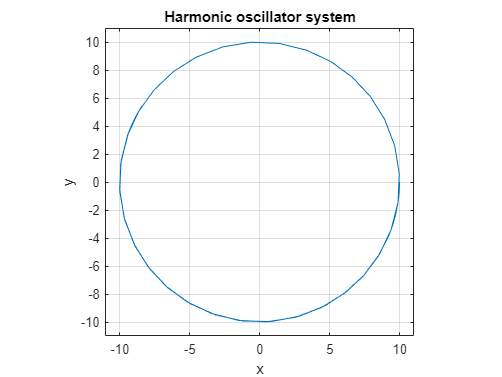

[T, XY]= ode45(@odefcn, [0 10], [10 0]);
plot(XY(:,1),XY(:,2)), grid on
xlabel("x"), ylabel("y"), xlim([-11 11]), ylim([-11 11])
pbaspect([1 1 1])
title("Harmonic oscillator system")

function dz=odefcn(t, z)
    dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)
    
    dz(1)=z(2);
    dz(2)=-z(1);
end